clear; clc; close all
load('20220817_191142_00.mat');


%% Radar parameters
c = physconst('LightSpeed'); %speed of light
BW = 4e9; %bandwidth
start_freq = 77e9;
end_freq = start_freq + BW;
fc = (start_freq + end_freq)/2; % carrier frequency
numADC = 256; % # of adc samples

NPpF = 256;
frameDuration = 40e-3;
T = frameDuration/NPpF; % PRI
PRF = 1/T;
F = numADC/T; % sampling frequency
dt = 1/F; % sampling interval
slope = BW/T;
lambda = c/fc;

Vmax = lambda/(T*4); % Max Unamb velocity m/s
DFmax = 1/2*PRF; % = Vmax/(c/fc/2); % Max Unamb Dopp Freq
dR = c/(2*BW); % range resol
Rmax = F*c/(2*slope); % TI's MIMO Radar doc
Rmax2 = c/2/PRF; % lecture 2.3
d_rx = lambda/2; % dist. between rxs
d_tx = 4*d_rx; % dist. between txs



t_onePulse = 0:dt:dt*numADC-dt;
numTX = 1;
numRX = 1;

% N_Dopp = numChirps; % length of doppler FFT
N_range = numADC; % length of range FFT
N_azimuth = numTX*numRX;
R = 0:dR:Rmax-dR; % range axis
% V = linspace(-Vmax, Vmax, numChirps); % Velocity axis
ang_ax = -90:90; % angle axis


%% Antennas
tx_loc = cell(1,numTX);
for i = 1:numTX
   tx_loc{i} = [(i-1)*d_tx 0 0];
%    scatter3(tx_loc{i}(1),tx_loc{i}(2),tx_loc{i}(3),'b','filled')
%    hold on
end

rx_loc = cell(1,numRX);
for i = 1:numRX
   rx_loc{i} = [tx_loc{numTX}(1)+d_tx+(i-1)*d_rx 0 0];
%    scatter3(rx_loc{i}(1),rx_loc{i}(2),rx_loc{i}(3),'r','filled')
end



%% Targets
fps_skel = 30;
num_tar = size(skel_hist,1);
durationx = size(skel_hist,3)/fps_skel;
numChirps = floor(durationx*NPpF*(1/frameDuration));
tar_loc = zeros(num_tar, size(skel_hist,2), numChirps*numADC);
for t = 1:num_tar
    for i = 1:size(skel_hist,2)
        tar_loc(t,i,:) = interp1(1:size(skel_hist,3), squeeze(skel_hist(t,i,:)), linspace(1,size(skel_hist,3),numChirps*numADC));      
    end
end


% temp = linspace(2.7, 0.5, numChirps*numADC);
% v_avg = (max(tar_loc(1,2,:)) - min(tar_loc(1,2,:))) * sqrt(3) / durationx;

delays_targets = cell(numTX,numRX,num_tar);

for t = 1:num_tar
    for i = 1:numTX
        for j = 1:numRX
            delays_targets{i,j,t} = (vecnorm(squeeze(tar_loc(t,:,:)) ...
                -repmat(rx_loc{j},size(tar_loc,3),1).',2,1) ...
                +vecnorm(squeeze(tar_loc(t,:,:)) ...
                -repmat(tx_loc{i},size(tar_loc,3),1).',2,1))/c; 
        end
    end
end



%% Complex signal
phase = @(tx,fx) 2*pi*(fx.*tx+slope/2*tx.^2); % transmitted
phase2 = @(tx,fx,r,v) 2*pi*(2*fx*r/c+tx.*(2*fx*v/c + 2*slope*r/c)); % downconverted

phase_t = phase(t_onePulse,fc);

mixed = zeros(numTX,numRX,size(tar_loc,3));
for i = 1:numTX
    for j = 1:numRX
        disp(['Processing Channel: ' num2str(j) '/' num2str(numRX)]);
        for t = 1:num_tar
            disp([int2str(t) '/' int2str(num_tar)]);
            
            for k = 1:numChirps
                phase_tar = phase(t_onePulse-delays_targets{i,j,t}(k*numADC),fc); % received
                signal_tar((k-1)*numADC+1:k*numADC) = exp(1j*(phase_t - phase_tar));
            end
            mixed(i,j,:) = squeeze(mixed(i,j,:)) + signal_tar.';
%             break
        end
    end
end

Processing Channel: 1/1


1/25
2/25
3/25
4/25
5/25
6/25
7/25
8/25
9/25
10/25
11/25
12/25
13/25
14/25
15/25
16/25
17/25
18/25
19/25
20/25
21/25
22/25
23/25
24/25
25/25


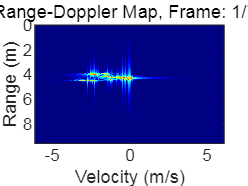

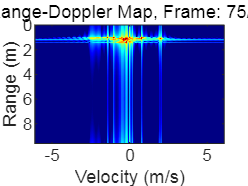


%% Post processing - 2-D FFT

% RDC = reshape(cat(3,mixed{:}),numADC,numChirps*numCPI,numRX*numTX); % radar data cube
RDC = reshape(mixed,numADC,numChirps,numRX*numTX);
numCPI = floor(numChirps/NPpF);
RDMs = zeros(numADC,NPpF,numTX*numRX,numCPI);
for i = 1:numCPI
    RD_frame = RDC(:,(i-1)*NPpF+1:i*NPpF,:);
    RDMs(:,:,:,i) = fftshift(fft2(RD_frame,[],[]),2);
end

figure
colormap(jet(256))
for f = 1:numCPI
    imagesc([-Vmax Vmax], [0 Rmax], 20*log10(abs(RDMs(:,:,1,f))/max(max(abs(RDMs(:,:,1,f))))));
    clim = get(gca,'clim');
    caxis([clim(1)/2 0])
%     title(['Frame ' int2str(f) '/' int2str(numCPI)]);
    xlabel('Velocity (m/s)');
    ylabel('Range (m)');
    title(['Range-Doppler Map, Frame: ' int2str(f) '/' int2str(numCPI)]);
    drawnow;
    F2(f) = getframe(gcf); % gcf returns the current figure handle
    pause(frameDuration)
end


writerObj = VideoWriter('test.avi');
writerObj.FrameRate = floor(1/frameDuration);
open(writerObj);

for i=1:length(F2)
        frame = F2(i) ;
        writeVideo(writerObj, frame);
end
close(writerObj);
   

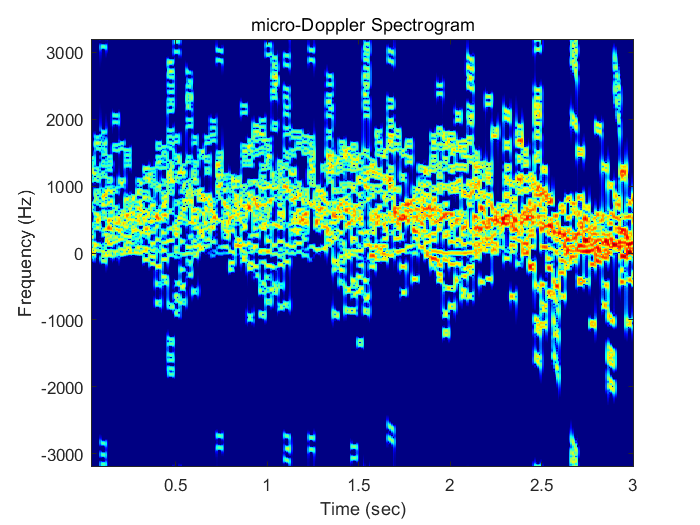

     
%% micro-Doppler spectrogram

rBin = 1:256;
nfft = 2^12;window = 256;noverlap = 200;shift = window - noverlap;
sx = myspecgramnew(sum(RDC(rBin,:,:)),window,nfft,shift); % mti filter and IQ correction
sx2 = abs(flipud(fftshift(sx,1)));
timeAxis = [1:numCPI]*frameDuration; % Time
freqAxis = linspace(-PRF/2,PRF/2,nfft); % Frequency Axis
fig = figure('visible','on');
colormap(jet(256));

doppSignMTI = imagesc(timeAxis,[-PRF/2 PRF/2],20*log10(abs(sx2/max(sx2(:)))));

title('micro-Doppler Spectrogram');
%     title(fOut(end-22:end-4))
xlabel('Time (sec)');
ylabel('Frequency (Hz)');
caxis([-45 0]) % 40
set(gca, 'YDir','normal')
set(gcf,'color','w');